## Multionomial

For each distribution, anwser the following questions:

- Is the RV discrete or continuous?

- What is the domain of the RV's PDF or PMF ?

- Describe the parameters of the distribution: how many are they? What values can they take?

- Give one example of real world phenomenon or data that could be modelled using the distribution.

and complete the following tasks:

- Plot the (theoretical) PDF (for contiuous RVs) or PMF (for discrete RVs) and the mean

- Draw a sample of $S=1000$ random outcomes.

- Plot the empirical PDF or PMF of these samples on the same plot created in task 1.

- Plot the (theoretical) CDF

- Plot the empirical CDF of the samples generated in task 2 on the same plot created in task 4.

- Use a Q-Q plot to show the similarity between empirical and theoretical quantiles.

Multinomial distribution is discrete

Output domain is > 0

One parameter: probabilities: user defined probabilities of each outcome

Examples include decay curves

pd = makedist('Multinomial', 'probabilities', ...
    [1, 2, 3, 4, 5, 6, 5, 4, 3, 2, 1]/36)

pd =   MultinomialDistribution

  Probabilities:
    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278



outcomes = 1:1:11;
multinomial_pdf = pdf(pd, outcomes)

multinomial_pdf =     0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278


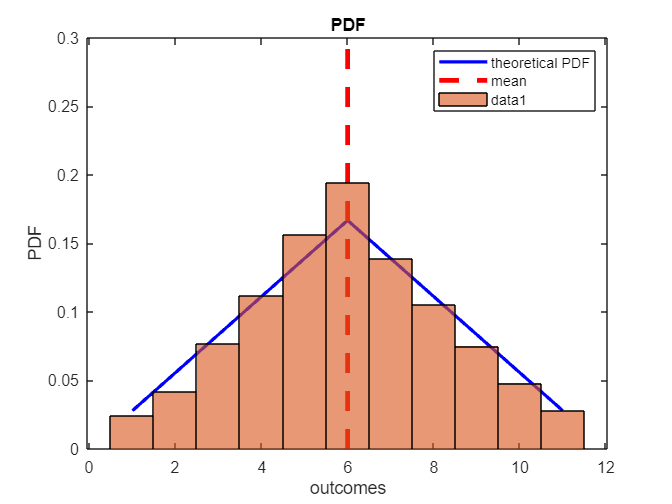

% Create small and large samples
sample = random(pd,1,1000);

% Generate plot data
clf; % clear the figure
plot(outcomes, multinomial_pdf, '-b', 'LineWidth', 2)
hold on
multinomial_mean = mean(pd); % Let's plot the distribution mean
line([multinomial_mean,multinomial_mean],[0,0.3], 'LineStyle', '--', 'Linewidth', 3,'Color','red');
legend('theoretical PDF', 'mean', 'Location','northeast')
title('PDF') % title for plot
xlabel('outcomes') % x-axis label
ylabel('PDF') % y-axis label

multinomial_epmf = histogram(sample, 'normalization', 'pdf'); % correctly normalised

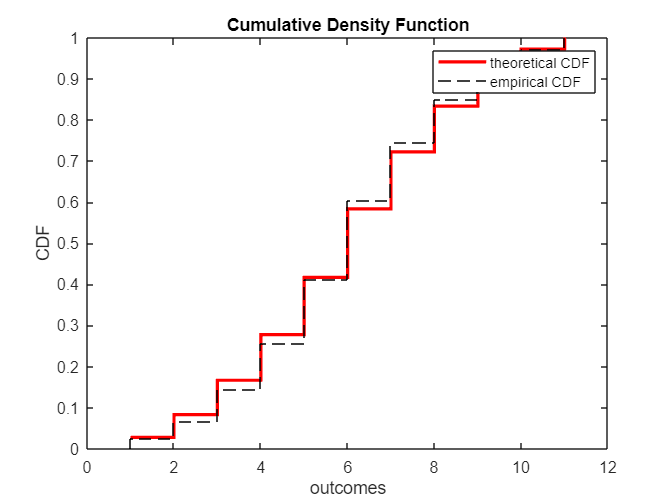

clf % clear the plot

% Theoretical value
multinomial_cdf = cumsum(multinomial_pdf);
stairs(outcomes, multinomial_cdf, 'r', 'LineWidth', 2)
hold on

% Emprical derivation
[exp_ecdf, x] = ecdf(sample);
stairs(x, exp_ecdf, 'k--')

title('Cumulative Density Function') % title for plot
xlabel('outcomes') % x-axis label
ylabel('CDF') % y-axis label
legend('theoretical CDF','empirical CDF')

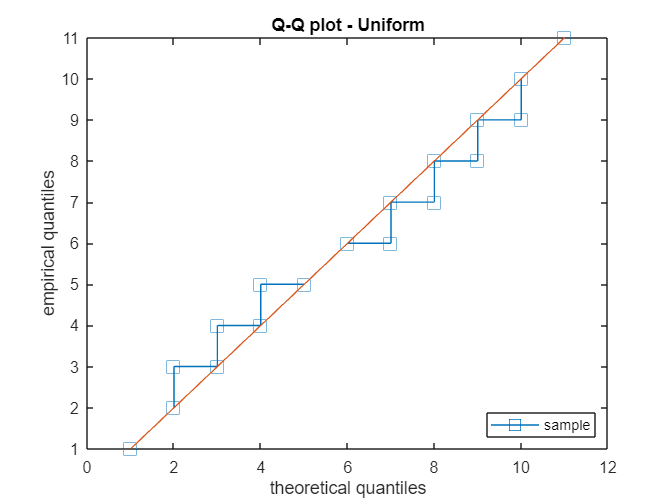

% evaluate at more points within 0 and 1
clf
pp = 0: 0.01: 1;
theor_q = icdf(pd, pp);
empir_q = quantile(sample, pp);
plot(theor_q, empir_q, 's-', 'MarkerSize', 10)
hold on
plot(theor_q, theor_q, '-','HandleVisibility','off')
legend('sample', 'Location','southeast')
title('Q-Q plot - Uniform') % title for plot
xlabel('theoretical quantiles') % x-axis label
ylabel('empirical quantiles') % y-axis label